`Author``: Luca Giaccone (`[luca.giaccone@polito.it](mailto:luca.giaccone@polito.it)`)`

clear variables, close all
clc

## **Esempio di computational notebook (Live Script Matlab)**

Analizziamo la potenza in regime sinusoidale.

Sian date una tensione ed una corrente così descritte


$$v(t) = \sqrt{2} V \sin(2 \pi f t + \varphi_v)$$



$$i(t) = \sqrt{2} I \sin(2 \pi f t + \varphi_i)$$


Poniamo, senza perdita di generalità $\varphi_i=0$ ed analizziamo la potenza:


$$p(t) = v(t) \:\: i(t)
$$


variando $\varphi_v$ nel range $\left[-\pi/2 \:\:,\:\: \pi/2\right]$

% fixed parameters
f = 50;
T = 1/f;
t = linspace(0, 2*T,500);

## Potenza in regime sinusoidale

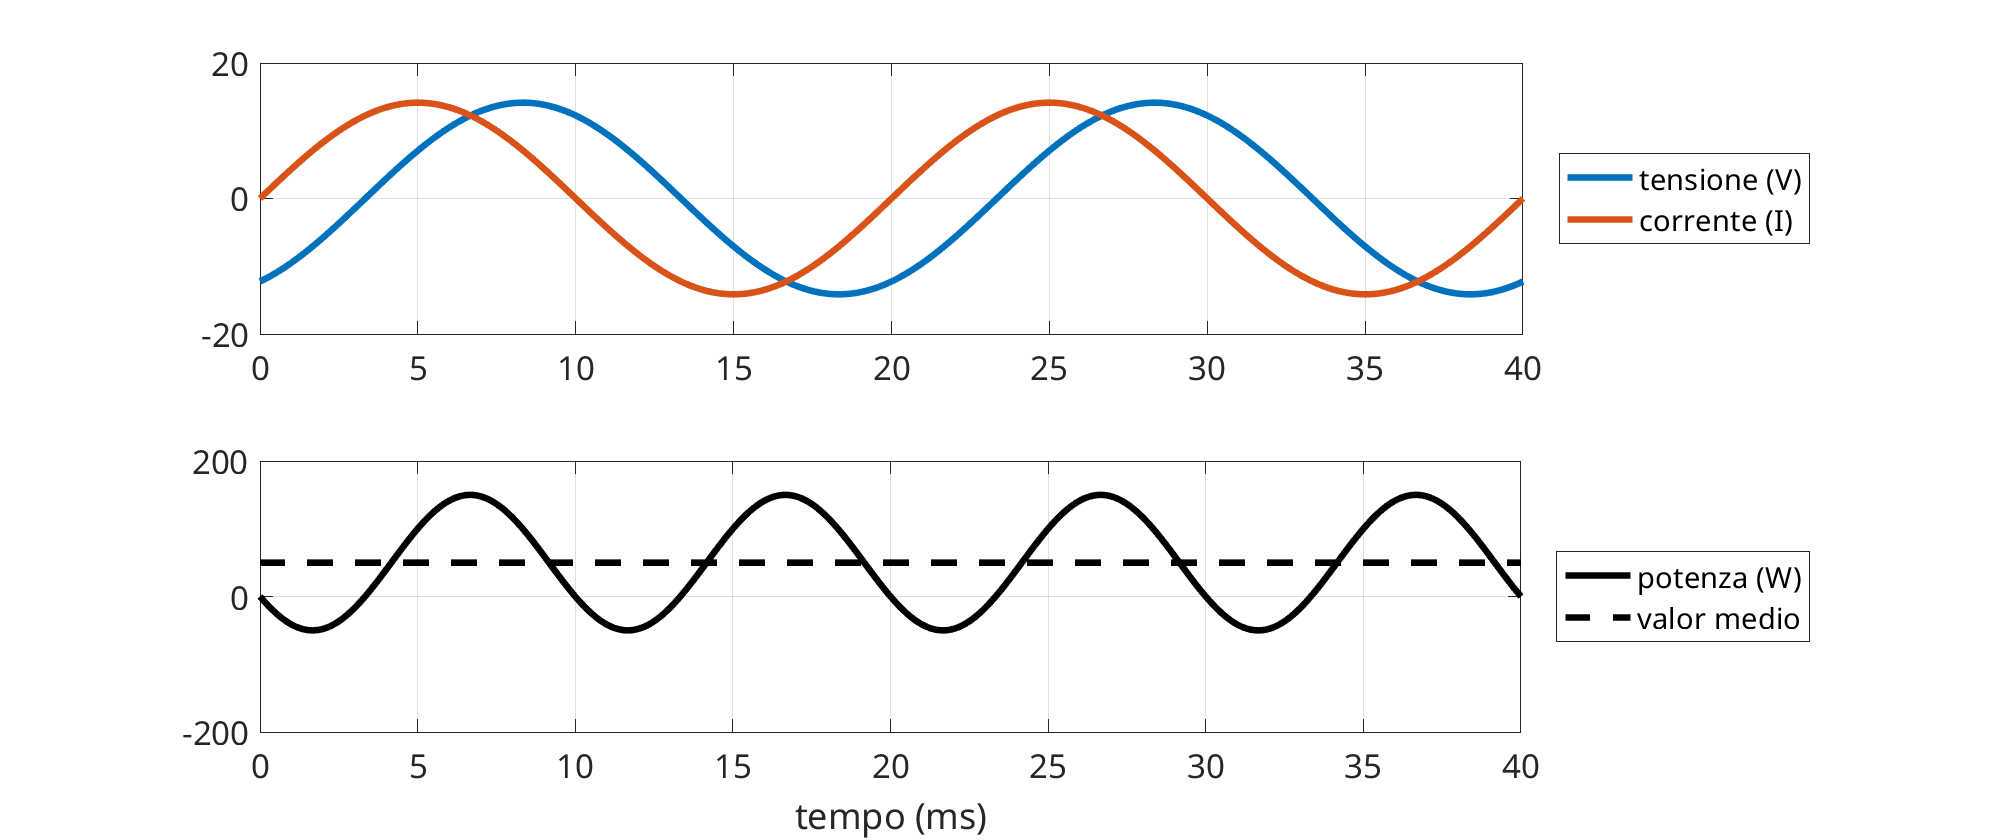

% fixed parameters
phi_v = -60;
fun(phi_v, f, t)

function fun(phi_v, f, t)
    V = 10;
    I = 10;
    phi_i = 0;
    v = sqrt(2) * V * sin(2 * pi * f * t + phi_v * pi / 180);
    i = sqrt(2) * I * sin(2 * pi * f * t + phi_i * pi / 180);
    p = v .* i;
    
    pave = sum(p) / length(p);
    
    figure;
    set(gcf, 'position', [489 343 1000 420])
    subplot(2,1,1)
    plot(t*1e3, v, 'LineWidth',3)
    hold on
    plot(t*1e3, i, 'LineWidth',3)
    grid on
    lg = legend('tensione (V)', 'corrente (I)');
    set(lg, 'location', 'eastoutside')
    set(gca, 'fontsize',15)
    
    subplot(2,1,2)
    plot(t*1e3, p, 'k', 'LineWidth',3)
    hold on
    plot(t*1e3, pave*ones(size(p)), 'k--', 'LineWidth',3)
    ylim([-200, 200])
    grid on
    lg = legend('potenza (W)', 'valor medio');
    set(lg, 'location', 'eastoutside')
    xlabel('tempo (ms)')
    set(gca, 'fontsize',15)
    
end
